# Modsim Project 2: How to Save Energy in the Winter

## Question

In the winter, people are often told to turn the heat down/off when they leave the house to save energy. However, there is also an argument that leaving the heat on when you leave is more efficient.  This model will seek to explain if there are any scenarios were leaving the heat on could be more energy efficient than turning it off when leaving the house for some amount of time.  Answering this question is important because it could resolve a potential spread of misinformation. In addition, it might help homeowners make more energy conscious decisions about their heating which would benefit their wallets and the environment.

**Learning Objectives**

Olivia

- Learn how to create a good modeling question

- Understand best practices in structuring a thermodynamic model

Rowan

- Want to write my own ODE’s / understand how to generate an equation for a modeling question

## Methodology

### Diagram

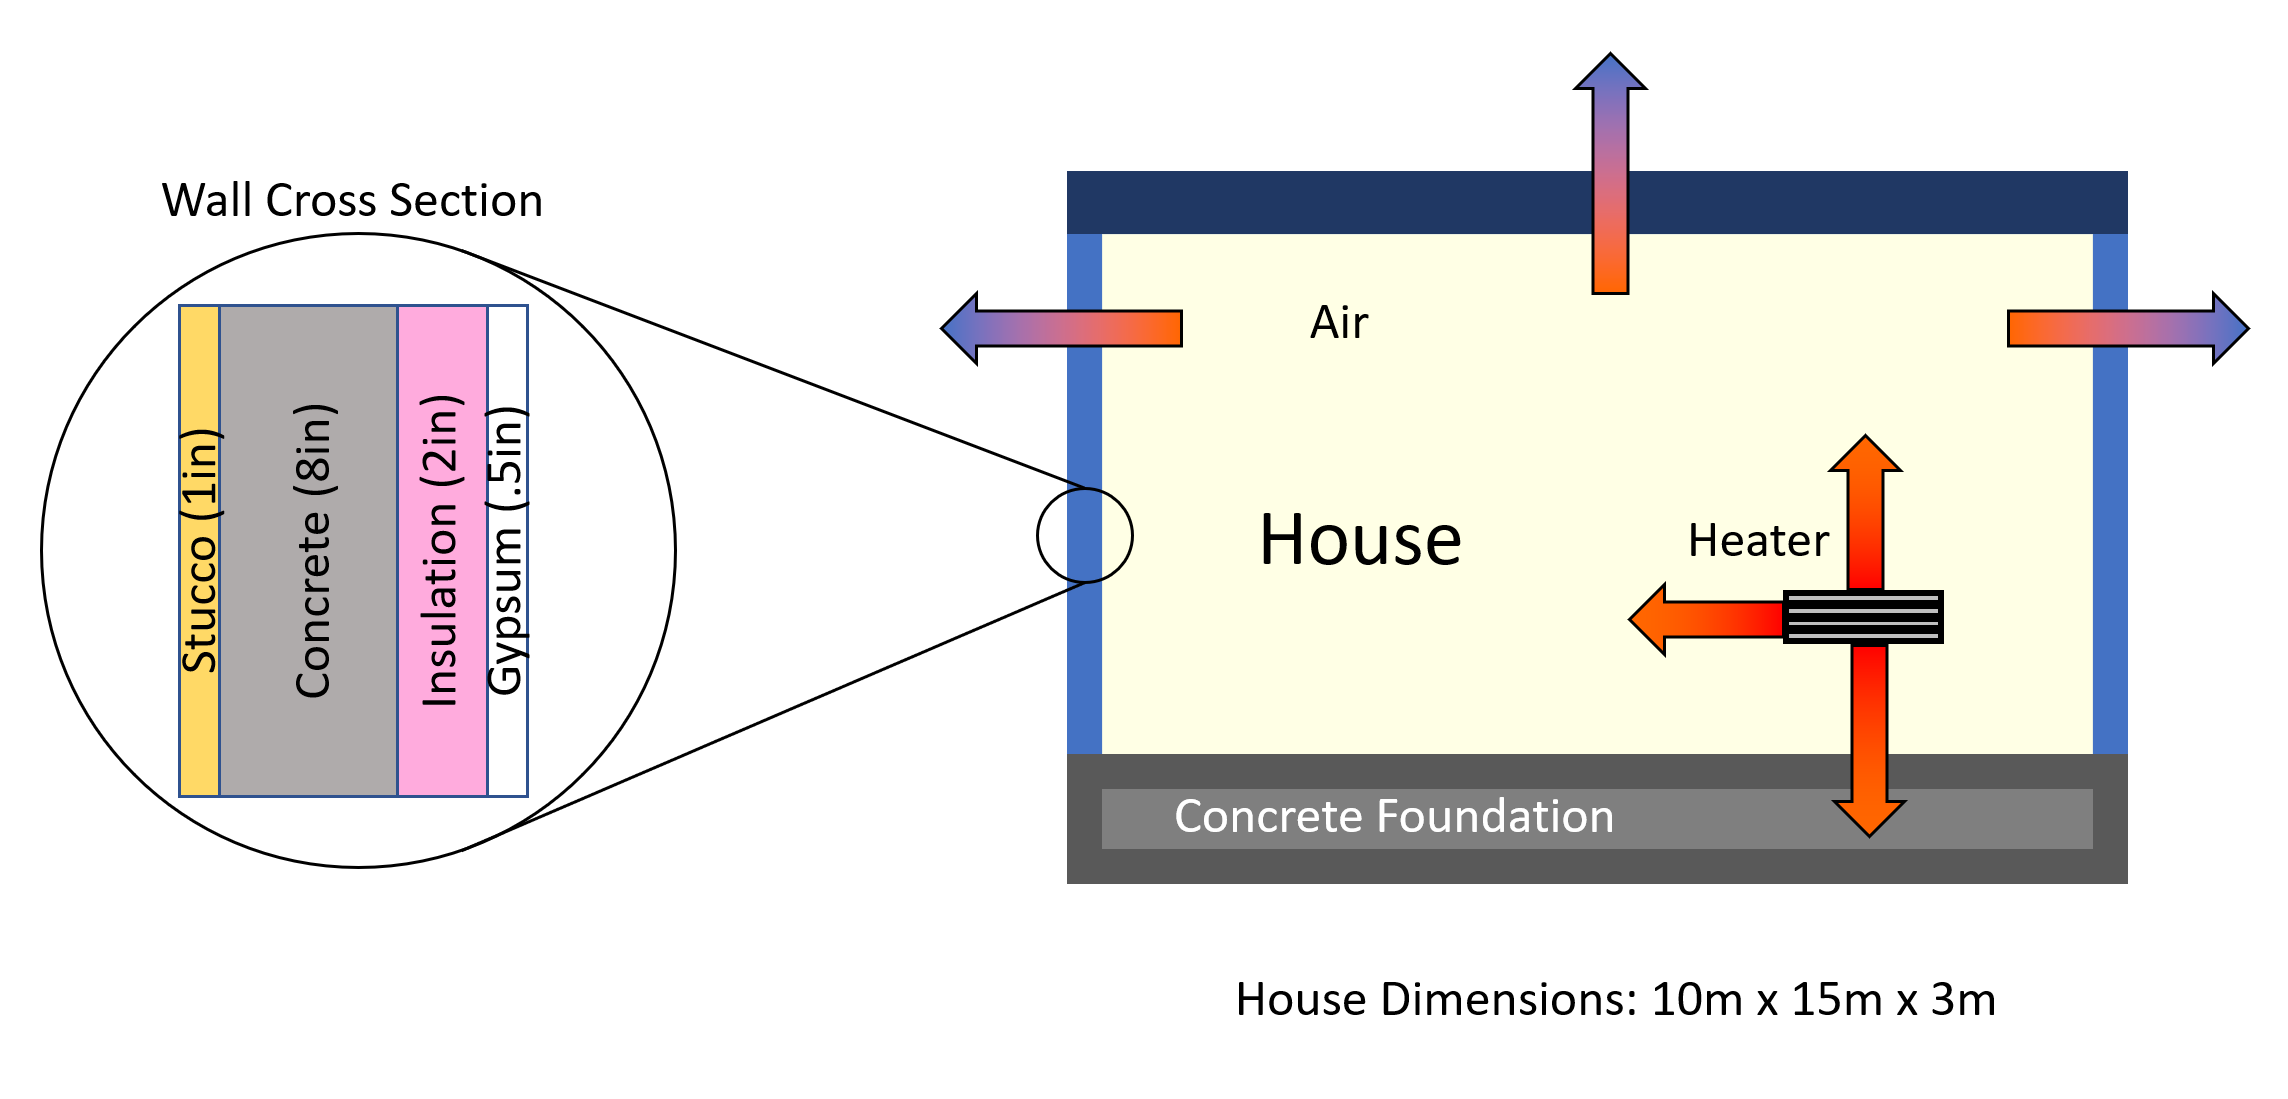

### Stock and Flow

To compare the efficiency of turning the heater off vs. leaving it on, a stock and flow model of a house was created.  In this model, the stock is the internal energy of the house. Energy flows in to the house from a heater and flows out of the house though conduction. When the heater is on, it adds energy at a constant rate (in watts) and when it is off, no heat is added. 

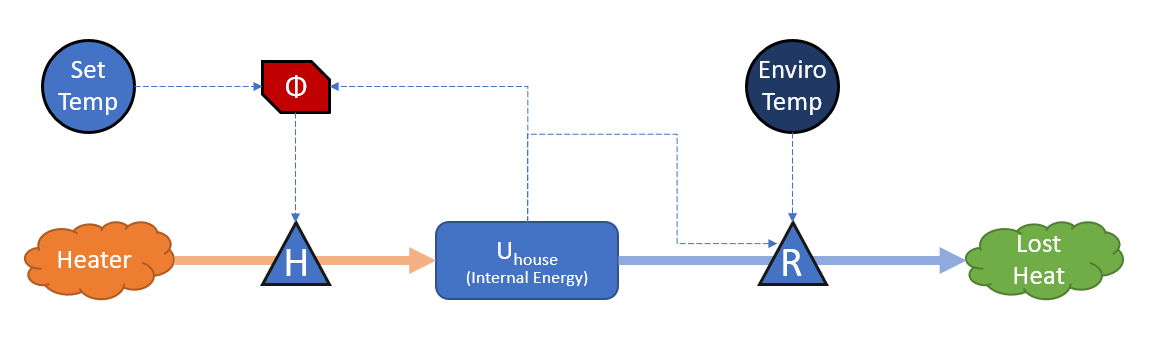

Flows in

- Gas Furnace Heating System: This is a forced input which depends on whether the house's current temperature is below the ideal temperature.

Flows out

- Conduction through walls and roof

### Mathematical Model

From the stock and flow diagram, the following differential equation is generated.


$$\frac{dU}{dt} = H\Phi - \frac{\Delta T}{R_{tot}}$$


 Where:

- $U$ is the internal energy of the house

- $H$ is the wattage of the heater

- $\Phi$ is a logical value indicating if the heater is on or off

- $\Delta T$ is the temperature difference between the house and the environment

- $R_{tot}$ is the total conductive resistivity of the house walls and roof

To calculate if the heater is on or off ($\Phi$), the model uses a discrete “overshoot and undershoot control band” which is commonly found in household thermostats. In this control algorithm, the heater overshoots the temperature set point by some buffer value and will not turn back on again until the heat in the house has dropped below the setpoint minus the buffer value. This causes the temperature of the house to oscillate around the set temperature and allows the heater to turn on less frequently.

This control system will be maintained in all scenarios while the set temperature will be varied to reflect keeping the heater on vs. turning it down or off. A parameter sweep can then be carried out to probe the effects of the different parameters in the model and compare the efficiencies of the scenarios.

To calculate the total energy ($E$) used by the heater in order to assess each scenario, the model also tracks $\frac{dE}{dt} = H\Phi$

### Parameters

- ideal house temp

- wattage heater

- solar radiation possibly

- thermal mass

- wall thickness

- roof thickness

- floor thickness + material

### Assumptions

In the model, there are several assumptions that are made.  Firstly, the house being modeled is very simple and it does not contain any internal walls, furniture, appliance, etc. Therefore, the thermal mass of the house can only be a crude estimate.  However, because this generalization will affect both scenarios, the model should still make informative relative comparisons.

In addition, all the house’s internal energy is modeled by a single stock. In other words, we are assuming that the system is quasi static. This is reasonable because the rate at which the heater heats the air likely slower than the rate the air heats the solid material in the house. 

### Global Variables/Conversions

Note: for every function that needs these variables, the first line of code `global k_to_c hours_to_seconds;` must be added in the top.

global k_to_c hours_to_seconds effective_off_temp;
k_to_c = 273;
hours_to_seconds = 60*60;
effective_off_temp = -10 + k_to_c;

### **Verification and Validation**

To verify the implementation of the model, a test scenario was generated where the house is subjected to changing daily temperatures for 3 days with no heater. The initial house temperature was 10 C. The results of this experiment are presented in the following figure. 

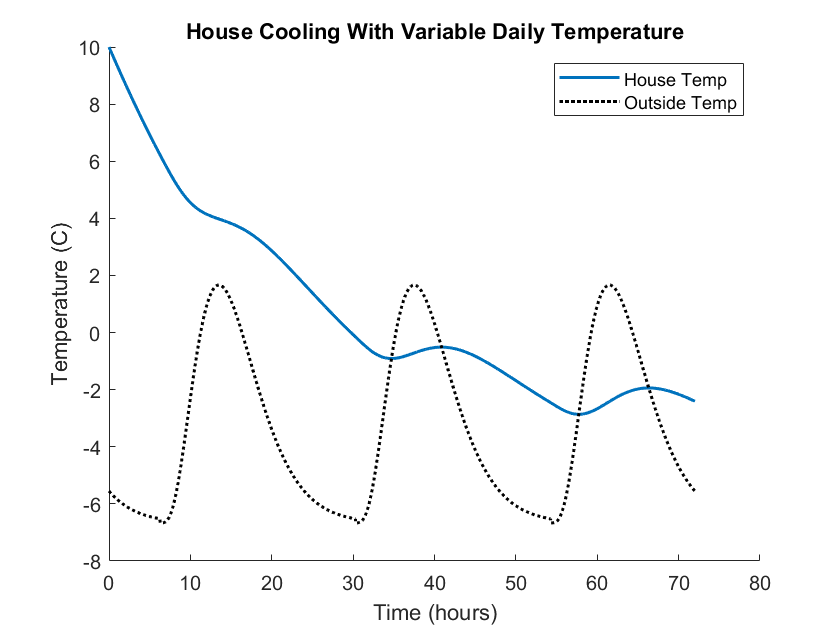

graph_title = "House Cooling With Variable Daily Temperature";
% Set temp is a row matrix with the value of the desired temperature at a
% given second. Allows us to simulate the user turning down the heat and
% turning it up.

%define row matrix with set temperatures over time
set_temp_range = [270*ones(1,72*hours_to_seconds)];

%call ODE solver
[time_range, temperature, ~, ~, outside_temp] = house_cooling(set_temp_range, 10 + k_to_c);

%plot results

figure(1)
clf
title(graph_title)
xlabel("Time (hours)")
hold on
plot(time_range / (hours_to_seconds), temperature-k_to_c, "Color", [0 0.4470 0.7410], "Linewidth", 1.5)
plot(time_range / (hours_to_seconds), outside_temp-k_to_c, "k:", "Linewidth", 1.5)
hold off
ylim([-8 10])
ylabel("Temperature (C)")
legend("House Temp", "Outside Temp")

As expected, this plot shows that the house temperature drops when the external temperature is cooler and rises when the external temperature is warmer. In addition, the lag between peaks in internal and external temperature are confimation of the presence of a significant thermal mass in the house.

In the next test, the heater control loop was enabled.  The house is initially at 15 C while the set temperature is set to 22 C for 6 hours, then the set temperature is turned "off" for 6 hours, finally the set temp is restored to 22 C for yet another 6 hours. "Off" is defined as -10 C which is far below the house temperature and minimum external temperature, so we can confidently assume that the house will never reach this temperature, meaning that the thermostat is effectively off.

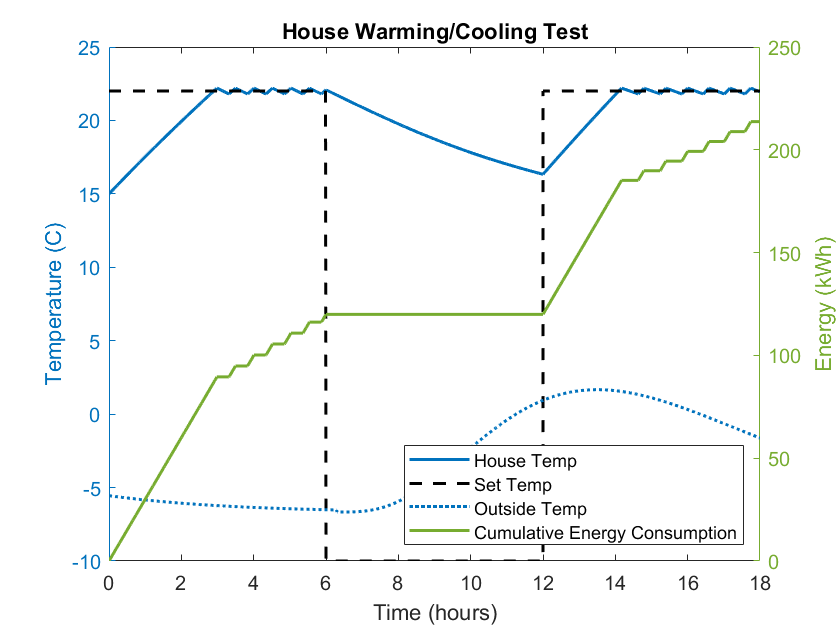

graph_title = "House Warming/Cooling Test";
% Set temp is a row matrix with the value of the desired temperature at a
% given second. Allows us to simulate the user turning down the heat and
% turning it up.

%define row matrix with set temperatures over time
set_temp_range = [(22 + k_to_c) *ones(1,6*hours_to_seconds), effective_off_temp*ones(1,6*hours_to_seconds), (22+k_to_c)*ones(1,6*hours_to_seconds)];

%call ODE solver
[time_range, temperature, energy_consumption, on_time, outside_temp] = house_cooling(set_temp_range, 15 + k_to_c);

%plot results
plotDefault(set_temp_range, time_range, temperature, energy_consumption, outside_temp, graph_title, [-10 25])

dispOnTime(on_time)

Total on time: 7.1233hours


One final verification is to multiply the wattage of the heater by the total on time. This value should match the total energy consumption at the end of the run.

on_time * 30000 == energy_consumption(end)

ans = logical
   1

## Results

### Parameter Sweep

To answer the modeling question, a sweep is performed for three different scenarios: leaving the set temp constant at 22C (leaving the heat on), turning the setpoint down to 13 C (turning the heat down), and turning the setpoint “off” (turning the heat off).  The sweeping parameter is the time “away-from-home” ranging from 0 hours to 8 hours.  

This results in the three different scenarios running for different lengths of time dependent on how long it takes for the house to come back up to temperature after having cooled off (on not cooled off in the case of the always-on heater scenario). To normalize around this, the energy consumption for each run in divided by the time of the run to get an average energy consumption per hour (in kilowatts).

In each run, the house is initially at 22C. Each run starts at 9AM when the person leaves the house and sets the `set_temp` to either 22C, 13C, or “off”.  The set_temp remains at that value for the duration of the away-from-home period (0-8 hours) after which the `set_temp` is set to 22C.  Each run ends when the house reaches 22C.  For the run where the `set_temp` is left on at 22C, the run ends immediately after the away-from-home period has elapsed.

The following plot shows the time away-from-home compared to the energy consumed in the run for each of the three scenarios.

## Interpretation

## Methodology

questions to consider

- what heating systems are there / how fast + energy efficient is the heating system

- house specifications

-     how big is the house

-     what kind of insulation

-     roof is flat, house is cube

- the outside world

-     ambient temperature + how it changes over the day

assumptions/things we are going to ignore

- the existence of night

- rooms - might affect the 

- in winter - ambient temperature always going to be colder

- convection is not significant enough of a energy loss that it needs to be modeled - lumping inside convection, walls conduction, outside convection

### Stocks

internal energy of the house

### Flows

### Defining our house

Our house is a cube with a flat roof

average sqft of a house in MA: 1,744 square feet = 162.022902 square meters

width = 10; % m
length = 15; % m
width*length % size of house in square meters
height = 3 % m, approx 10 ft
% define thermal mass
% add windows

#### Stock and Flow


$$\frac{dU}{dt} = P_{heater} + P_{sun}  - \frac{\Delta T}{R_{tot}}$$


ans = 150

height = 3